# Trajectory Generation

## Load the map

load maps/complexmap2.mat;
Resolution=0.1; % meters
map = binaryOccupancyMap(complexMap,Resolution);
uavRadius = .5;

% inflate map
inflate(map,uavRadius);

## Create waypoints

start = [50 25];
waypoint1 = [30 150];
waypoint2 = [200 235];
waypoint3 = [100 350];
waypoint4 = [410 380];
waypoint5 = [450 50];
waypoint6 = [200 30];
waypoints = [waypoint1; waypoint2; waypoint3; waypoint4; waypoint5; waypoint6];

## Visualize map and waypoints

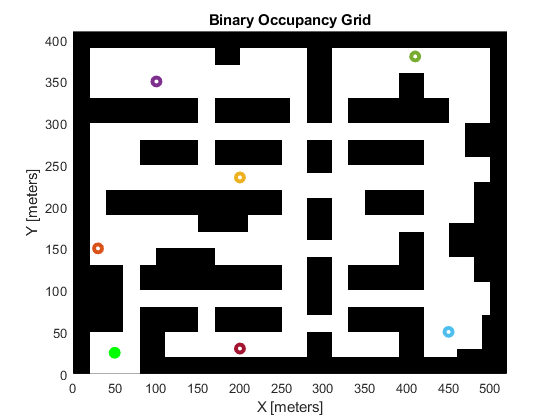

f1 = figure(1); clf;
hold on;
show(map);
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
hold off;

## Build PRM

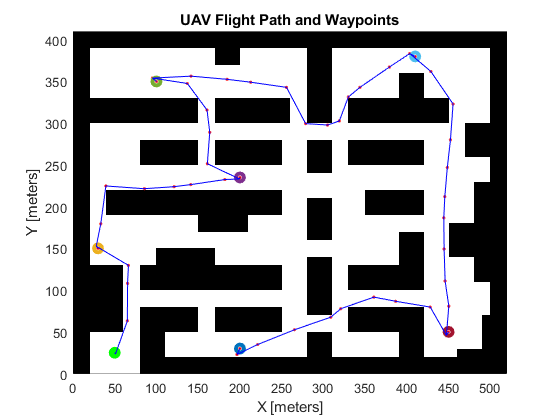

prm = mobileRobotPRM;
prm.Map = mapInflated;

prm.NumNodes = 1000;
prm.ConnectionDistance = 50;

path = findpath(prm, start, waypoint1);
for i = 2:length(waypoints)
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end
f2 = figure(2); clf;
hold on;
show(map);
plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(path-1)
    plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

## Calculate flight parameters

flight parameters
desiredvelocity=1.3; % m/s
totaldistancei = calculatedistance(path); % total distance to be covered
timeinterval = calculatetime(totaldistancei,desiredvelocity); 
stoptimetotal=timeinterval(2)+0.25*timeinterval(2); % time to complete the mission

% generate smooth time stamped trajectory
sampletimetraj=1; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:timeinterval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',timeinterval,tSamples);
XrefTot=[tSamples',q(1,:)'];
YrefTot=[tSamples',q(2,:)'];

path2stamped.XrefTot = XrefTot;
path2stamped.YrefTot = YrefTot;
save('path2stamped.mat', 'XrefTot', "YrefTot");
path2 = [q(1,:) ;q(2,:)]';
save('path2.mat', 'path');